Script to compute sensitivity for Fig. W4.10 by first inputting the data for the component transfer functions Tij and the nominal parameter Kcl for this problem

 Kcl=9; tau=0.01;
 n11=0; d11=1;
 n12=1; d12=1;
 n22=-1; d22= [tau 1];
 n21=1; d21=[tau 1];

Now compute the numerator and denominator polynomials of the transfer functions using the convolution function `conv` to multiply the polynomials and put them into system transfer function forms with the MATLAB function `tf`; the overall transfer function is Y/R = n11/d11 + (n12n21d22)/(d12d21[d22 − Kcln22]) = sysy, and the transfer function from the reference input to the sensitivity is Kcl(dy/dKcl)/R = sysdy; now define the numerators and denominators of several intermediate transfer functions.

n1=Kcl*conv(n21,n12);
d1=conv(d21,d12);
n2=d22;
d2=d22-Kcl*n22;
ny=conv(n1,n2);
dy=conv(d1,d2);

Now put these together to form two intermediate transfer functions.

sysy1 = tf(ny,dy);
sysy2 = tf(n11,d11);

Now construct the final transfer functions, the overall transfer function Y/R.

sysy=sysy1+sysy2;

The sensitivity transfer function.

ndy=conv(ny,n2);
ddy=conv(dy,d2);
sysdy=tf(ndy,ddy);

Now use these to compute the step responses and plot the output, the sensitivity, and a perturbed response.

[y, t1] = step(sysy);
[yd, t2] = step(sysdy);

% Combine the time vectors and make them the same length
t = linspace(min(t1(1), t2(1)), max(t1(end), t2(end)), max(length(t1), length(t2)));

% Interpolate both step responses onto the same time vector
y = interp1(t1, y, t, 'linear', 'extrap');
yd = interp1(t2, yd, t, 'linear', 'extrap');

% Now plot separately to avoid size mismatch
figure;
plot(t, y, t, yd, t, y + 0.1 * yd);
legend('Output (y)', 'Sensitivity (yd)', 'Perturbed Response (y + 0.1*yd)');

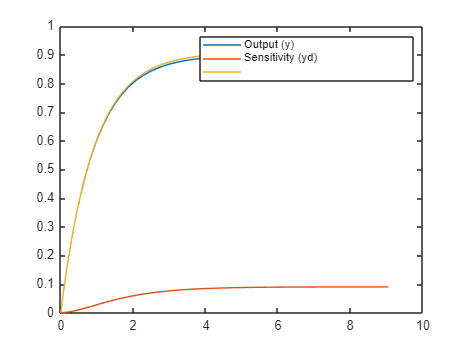


legend(["Output (y)", "Sensitivity (yd)", "Perturbed Response (y + 0.1*yd)"])